# **Non Linear Equations of Motion for a Pole-Card System**

clear; format compact

### Part 0. System Definition and Parameter Declaration

Non-linear equations of motion for the system are derived using the euler-lagrange method as described in [this article](https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=SystemModeling).

% Define the symbolic variables
syms x(t) theta(t) U
syms m M l b I g real

% Define the equations of motion
Eq1 = (M + m) * diff(x(t), t, 2) + b * diff(x(t), t) + ...
            m*l*diff(theta(t), t, t)*cos(theta(t)) - ...
            m*l*diff(theta(t), t)*sin(theta) == U;

Eq2 = (I + m*l^2)*diff(theta(t), t, 2) + m*g*l*sin(theta(t)) ...
        == -m*l*diff(x(t), t, 2)*cos(theta(t));

Eq = [Eq1; Eq2], vars = [x(t), theta(t)]

$$Eq(t) = \begin{array}{l} \left(\begin{array}{c} b\,\frac{\partial }{\partial t}x\left(t\right)+\left(M+m\right)\,\sigma_{1}-l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}=U\\ \left(m\,l^{2}+\text{I}\right)\,\sigma_{2}+g\,l\,m\,\sin\left(\theta \left(t\right)\right)=-l\,m\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

$$vars = \left(\begin{array}{cc} x\left(t\right) & \theta \left(t\right) \end{array}\right)$$

### Part 1. NonLinear State Space Form Derivation from Equations of Motion

After implementing the second order ODEs, we have to manipulate it to be in a get the state space representation of it.

% Turn to a Single Order Set of ODEs as State Space Representation
[V, S, tmp] = reduceDifferentialOrder(Eq, vars);
[M_eqns, f_eqns] = massMatrixForm(V, S);
StSp = simplify(M_eqns \ f_eqns);

% Rename State Variables to x
SysOrder = numel(S);
syms x [SysOrder 1] real
StSp = subs(StSp, S, x)

$$StSp = \begin{array}{l} \left(\begin{array}{c} x_{3}\\ x_{4}\\ \frac{\text{I}\,U-\text{I}\,b\,x_{3}+U\,l^{2}\,m+l^{3}\,m^{2}\,x_{4}\,\sin\left(x_{2}\right)-b\,l^{2}\,m\,x_{3}+\frac{g\,l^{2}\,m^{2}\,\sin\left(2\,x_{2}\right)}{2}+\text{I}\,l\,m\,x_{4}\,\sin\left(x_{2}\right)}{\sigma_{1}}\\ -\frac{l\,m\,\left(U\,\cos\left(x_{2}\right)-b\,x_{3}\,\cos\left(x_{2}\right)+g\,m\,\sin\left(x_{2}\right)+M\,g\,\sin\left(x_{2}\right)+l\,m\,x_{4}\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(x_{2}\right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M \end{array}$$

### Part 2. Linearization

#### Part 2.1 Substitute Real Values

Then the real values are substituted for the symbolic variables.

SS = subs(StSp, [  M,   m,   b,   l,     I,    g], ...
                [0.5, 0.2, 0.1, 0.3, 0.006, 9.81]);

% Number of Decimal Points Precision
precision = 3;              
SS = vpa(SS, precision)

$$SS = \left(\begin{array}{c} x_{3}\\ x_{4}\\ -\frac{1.0\,\left(0.024\,U-0.0024\,x_{3}+0.0177\,\sin\left(2.0\,x_{2}\right)+0.00144\,x_{4}\,\sin\left(x_{2}\right)\right)}{0.0036\,{\cos\left(x_{2}\right)}^{2}-0.0168}\\ \frac{0.06\,\left(6.87\,\sin\left(x_{2}\right)+U\,\cos\left(x_{2}\right)-0.1\,x_{3}\,\cos\left(x_{2}\right)+0.06\,x_{4}\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)\right)}{0.0036\,{\cos\left(x_{2}\right)}^{2}-0.0168} \end{array}\right)$$

#### Part 2.2 Linearize Model and Export as Linear State Space Format

Using the first order Taylors Series Expantion, the system in linearized around a working point that is considered as all zeros.

% Working/Equilibrium Point
x_eq = [0; 0; 0; 0];  
U_eq = 0; 

% A and B Matrices Creation
A = jacobian(SS, x);
B = jacobian(SS, U);

% Substitute Equivalent Values for A and B
A = subs(A, [x; U], [x_eq; U_eq]); A = double(A);
B = subs(B, [x; U], [x_eq; U_eq]); B = double(B);

C = [1, 0, 0, 0
     0, 1, 0, 0];
D = [0; 0];

% System Order
n = size(A, 1);

% Final State Space Form
states = {'X', 'Phi', 'dX', 'dPhi'};
inputs = {'U'};
outputs = {'Phi'};
Sys = ss(A, B, C, D, 'statename', states, 'inputname', inputs, 'outputname', outputs)

Sys =
 
  A = 
               X      Phi       dX     dPhi
   X           0        0        1        0
   Phi         0        0        0        1
   dX          0    2.675  -0.1818        0
   dPhi        0   -31.21   0.4545        0
 
  B = 
              U
   X          0
   Phi        0
   dX     1.818
   dPhi  -4.545
 
  C = 
              X   Phi    dX  dPhi
   Phi(1)     1     0     0     0
   Phi(2)     0     1     0     0
 
  D = 
           U
   Phi(1)  0
   Phi(2)  0
 
Continuous-time state-space model.


#### Part 2.3 Creation of Some Realizations

To create the realizations, a orthonormal matrix is created as a random modal matrix and a new system is created based on that.

RealizationNo = 4;

for R = 1:RealizationNo
    % Create a Random Orthonormal Modal Matrix
    Q = orth(rand(n));
    
    % Create a New Realization
    Anew = inv(Q) * A * Q;
    Bnew = inv(Q) * B;
    Cnew = C * Q;
    Dnew = D;
    SysNew = ss(Anew, Bnew, Cnew, Dnew);

    % Print information about the new realization
    disp('=====================================================================')
    fprintf('System Realization %d:\n', R);
    
    % Print A, B, C, and D separately
    fprintf('A:\n');
    disp(SysNew.A);
    
    fprintf('\nB:\n');
    disp(SysNew.B);
    
    fprintf('\nC:\n');
    disp(SysNew.C);
    
    fprintf('\nD:\n');
    disp(SysNew.D);
    
    fprintf('\n');
end

System Realization 1:


A:


   -3.7389  -10.2787   -0.4406   -6.4924
   -2.1204   -5.1174   -1.1579   -3.5165
    6.8340   17.5134    0.5863   10.5378
    6.4044   14.3281    0.8823    8.0882



B:


    0.9565
    1.1400
   -4.1467
   -2.1349



C:


   -0.5314    0.5395    0.3191   -0.5698
   -0.3373   -0.8080   -0.0528   -0.4801



D:


     0
     0


System Realization 2:


A:


   -4.9610    1.7800    0.9822   -5.2371
   11.9167   -4.2677   -3.0498   10.8306
   11.5863   -3.0378   -3.0248    9.7323
   14.2338   -5.3548   -4.0445   12.0716



B:


    0.4293
   -3.6504
   -2.0579
   -2.4944



C:


   -0.4361    0.1887   -0.8181    0.3238
   -0.7229    0.2314    0.1925   -0.6220



D:


     0
     0


System Realization 3:


A:


  -10.4945   -1.5299    5.5049    7.8427
   18.2307    1.8462   -7.7502  -12.6621
   -3.6442   -0.1412    1.3098    2.2940
  -10.9957   -0.4712    5.5337    7.1566



B:


    1.7839
   -3.8121
   -0.6472
    2.4153



C:


   -0.3753   -0.6220    0.0836   -0.6821
   -0.7694   -0.0780    0.3387    0.5359



D:


     0
     0


System Realization 4:


A:


  -12.3786    1.5398    7.9531   -9.7160
  -11.5860    0.8419    5.9896   -8.7248
   -1.7990   -0.0572    0.9925   -0.8353
   15.1086   -1.0755   -9.0425   10.3624



B:


    2.3492
    2.0842
   -0.9102
   -3.6436



C:


   -0.3276    0.8431   -0.2620    0.3365
   -0.7293    0.0614    0.4167   -0.5392



D:


     0
     0


### Part 3. Control

#### Part 3.1 Controllability Check

% Controllability Matrix Creation
CtrbMat = ctrb(Sys);

% Controllability Check
if rank(CtrbMat) == n
    disp(' >> The system is controllable.');
    disp('Controllability Matrix:');
    disp(CtrbMat);
else
    disp(' >> The system is not controllable.');
    disp('Controllability Matrix:');
    disp(CtrbMat);
end

 >> The system is controllable.


Controllability Matrix:


         0    1.8182   -0.3306  -12.1011
         0   -4.5455    0.8264  141.7299
    1.8182   -0.3306  -12.1011    4.4113
   -4.5455    0.8264  141.7299  -31.2969


#### Part 3.2 Observability Check

% Observability Matrix Creation
ObsvMat = obsv(Sys);

% Observability Check
if rank(ObsvMat) == n
    disp('The system is observable.');
    disp('Observability Matrix:');
    disp(ObsvMat);
else
    disp('The system is not observable.');
    disp('Observability Matrix:');
    disp(ObsvMat);
end

The system is observable.


Observability Matrix:


    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
         0    2.6755   -0.1818         0
         0  -31.2136    0.4545         0
         0   -0.4864    0.0331    2.6755
         0    1.2161   -0.0826  -31.2136


#### Part 3.3 Controller and Observer Design

% State Feedback Controller Design
ContollerPoles = [-1-2j, -1+2j, -2-1j, -2+1j];
K = place(A, B, ContollerPoles);

% State Feedback Controller Design
ObserverPoles = [-1-2j, -1+2j, -2-1j, -2+1j];
L = place(A', C', ObserverPoles)';

% Display Gain Matrices
disp(['State Feedback Gain (K): ' mat2str(K, 2)]), disp(['State Observer Gain (L): ' mat2str(L, 2)])

State Feedback Gain (K): [0.56 3.1 0.57 -1.1]
State Observer Gain (L): [2.9 0.81;-0.7 3;3.3 5.4;-1.8 -27]


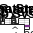

% Calculate the Augmented System Char Matrices
Aaug = [  A,      -B*K
        L*C, A-B*K-L*C];
  
Baug = [B
        B];

Caug = [C -D*K];

Daug=D;

% System Object Creation
SysAug = ss(Aaug, Baug, Caug, Daug);

% Time vector for simulation
t = 0:0.01:20;

% Initial States
% x0 = [pi, 0.1, 0, 0, 0.2, 0, 0, 0];
x0 = rand(1, 8)*3;

% Simulate the closed-loop system
[y, t, x] = lsim(SysAug, zeros(size(t)), t, x0);

% Plot the output
figure;
subplot(2, 2, [1, 2]);
plot(t, y, 'LineWidth', 2);
title('Closed-Loop System Output');
xlabel('Time');
ylabel('Output');
legend({'Output $X$', 'Output $\phi$'}, 'Interpreter', 'latex');
grid on

% Plot all states
subplot(2, 2, 3);
plot(t, x, 'LineWidth', 2);
title('System States');
xlabel('Time');
ylabel('States');
legend({'$X$', '$\phi$', '$\dot{X} $', '$\dot{\phi}$', ...
        'Est. $X$', 'Est. $\phi$', 'Est. $\dot{X} $', 'Est. $\dot{\phi}$'}, ...
        'Interpreter', 'latex', 'NumColumns', 2);
ylim([-4, 8])
grid on

% Estimation Error
subplot(2, 2, 4);
Err = x(:, 4) - x(:, 5:end);
plot(t, Err, 'LineWidth', 2);
title('Estimation Errors');
xlabel('Time');
ylabel('States');
legend({'$\hat{X}$', '$\hat{\phi}$', '$\hat{\dot{X}}$', '$\hat{\dot{\phi}}$'},...
        'Interpreter', 'latex', ...
        'NumColumns', 2);
ylim([-4, 8])
grid on

% Adjust subplot layout
sgtitle('Closed-Loop System Simulation');